## Human Action Recognition

Loading dataset

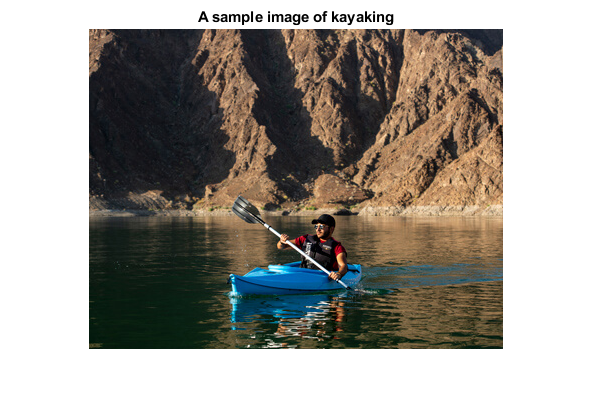

Dataset = imageDatastore('Dataset', ...
    'IncludeSubfolders', true, ...
    'LabelSource', 'foldernames');

kayaking = find(Dataset.Labels == 'kayaking', 1);
imshow(readimage(Dataset, kayaking));
title('A sample image of kayaking')

countLabels = countEachLabel(Dataset);
display(countLabels);

countLabels = 12×2 table
        Label         Count
    ______________    _____

    Photographing      142 
    bike_riding        153 
    driving            146 
    eating             147 
    horse_riding       115 
    kayaking           140 
    playing_music      171 
    pushups            137 
    running            166 
    swimming           121 
    using_computer      85 
    walking            160 


Splitting data into training and validation set

[train_set, valid_set] = splitEachLabel(Dataset, 7.0);

Viewing network architecture

net = googlenet;
analyzeNetwork(net);

layer1 = net.Layers(1);
input_size = layer1.InputSize(1:2);
train_set_resized = augmentedImageDatastore(input_size, train_set, 'ColorPreprocessing', 'gray2rgb');
valid_set_resized = augmentedImageDatastore(input_size, valid_set, 'ColorPreprocessing', 'gray2rgb');
feature_learner = net.Layers(142);
output_classifier = net.Layers(144);
num_classes = numel(categories(train_set.Labels))

num_classes = 12

Defining new layers

new_feature_learner = fullyConnectedLayer(num_classes, ...
    'Name', 'Human Action Learner', ...
    'WeightLearnRateFactor', 10, ...
    'BiasLearnRateFactor', 10);

new_classifier_layer = classificationLayer('Name', 'Human Action Classifier');

Modyfing googlenet layers

layer_graph = layerGraph(net);
new_layer_graph = replaceLayer(layer_graph, feature_learner.Name, new_feature_learner);
new_layer_graph = replaceLayer(new_layer_graph, output_classifier.Name, new_classifier_layer);
analyzeNetwork(new_layer_graph);

minibatch_size = 8;
validation_freq = floor(numel(train_set_resized.Files)/minibatch_size);
training_options = trainingOptions('sgdm', ...
    'MiniBatchSize', minibatch_size, ...
    'MaxEpochs', 50,...
    'InitialLearnRate', 3e-4, ...
    'Shuffle', 'every-epoch', ...
    'ValidationData', valid_set_resized, ...
    'ValidationFrequency', validation_freq, ...
    'Verbose', true, ...
    'Plots', 'training-progress');

Training

Training on single CPU.
Initializing input data normalization.
|======================================================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Validation  |  Mini-batch  |  Validation  |  Base Learning  |
|         |             |   (hh:mm:ss)   |   Accuracy   |   Accuracy   |     Loss     |     Loss     |      Rate       |
|======================================================================================================================|
|       1 |           1 |       01:35:26 |       37.50% |        7.44% |       2.9827 |       4.0722 |          0.0003 |
|       1 |          10 |       01:40:01 |       25.00% |       53.22% |       3.5032 |       1.5447 |          0.0003 |
|       2 |          20 |       01:44:16 |       62.50% |       63.16% |       0.8979 |       1.0487 |          0.0003 |
|       3 |          30 |       01:48:28 |       87.50% |       72.05% |       0.2081 |   

|      47 |         470 |       05:39:54 |      100.00% |       78.55% |       0.0004 |       0.7041 |          0.0003 |
|      48 |         480 |       05:44:50 |      100.00% |       78.61% |       0.0008 |       0.7046 |          0.0003 |
|      49 |         490 |       05:49:41 |      100.00% |       78.55% |       0.0001 |       0.7050 |          0.0003 |
|      50 |         500 |       05:54:36 |      100.00% |       78.36% |       0.0005 |       0.7066 |          0.0003 |
|======================================================================================================================|
Training finished: Max epochs completed.


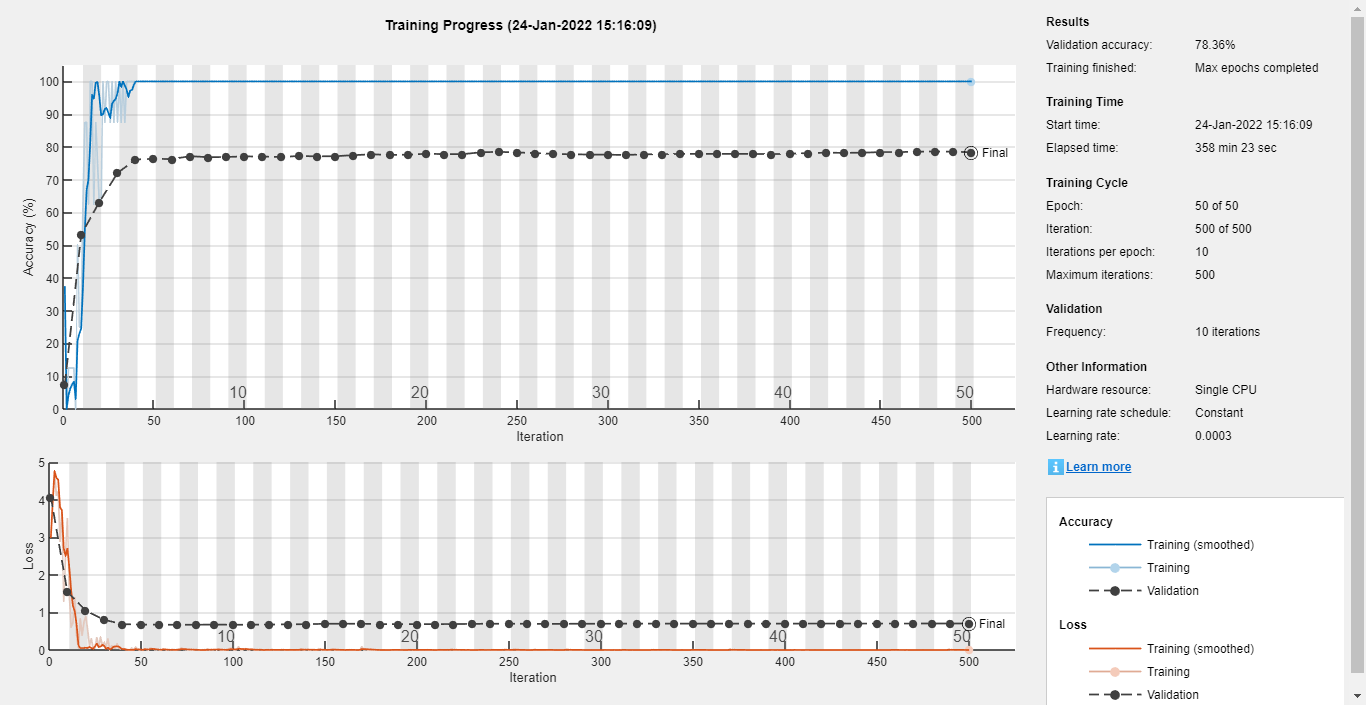

net = trainNetwork(train_set_resized, ...
    new_layer_graph, ...
    training_options);

Loding our trained model

net = coder.loadDeepLearningNetwork('gnet.mat');

Recognizing human actions

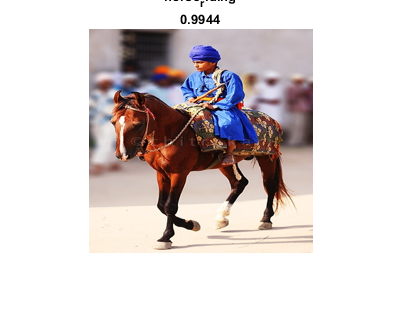

test_recognizer(net, 'test/a10.jpg');